% Example_5_5.mlx
%
% This is Example 5.5 from the paper 'Laguerre tessellations and 
% polycrystalline microstructures: A fast algorithm for generating grains 
% of given volumes' by D.P. Bourne, P.J.J. Kok, S.M. Roper, W.D.T. Spanjer
% (Philosophical Magazine 100, 2677-2707, 2020).
%
% We generate a 3D periodic Laguerre diagram with 10,000 grains of given 
% volumes, where the grain volumes are drawn from a log-normal 
% distribution, using Algorithm 2 of the above paper. 

clear

tic

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

n=10000; % number of grains

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Specify whether the Laguerre diagram is periodic (periodic=true) or
% non-periodic (periodic=false)

periodic=true; 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Define the geometry. We create a 3D periodic Laguerre diagram in a 
% rectangular box with vertices (0,0,0), (L1,0,0), (0,L2,0), (0,0,L3), 
% (L1,L2,0), (L1,0,L3), (0,L2,L3), (L1,L2,L3).

L1=2; % length of the box in the x-direction
L2=2; % length of the box in the y-direction
L3=2; % length of the box in the z-direction
bx=[L1,L2,L3];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Specify the desired volumes of the grains, which are drawn from a 
% log-normal distribution

ln_mean=1; % mean
std_dev=0.35; % standard deviation
Sigma=sqrt((log(1+(std_dev/ln_mean)^2))); % log-normal parameter sigma
Mu=-0.5*Sigma^2+log(ln_mean); % log-normal parameter mu

% Draw the radii from the log-normal distribution
radii=lognrnd(Mu,Sigma,[n,1]);

% Calculate the corresponding grain volumes 
% (note that we don't need the factor 4pi/3 as we'll be renormalising)
target_vols=radii.^3;

% Normalise the volumes so that they add to the volume of the box
target_vols=...
    target_vols*L1*L2*L3/sum(target_vols); % target volumes of the grains

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Choose the optimisation solver

solver='dampedNewton'; % damped Newton method (recommended)
% solver='fminunc'; % slower option

% Remark:
% In the paper 'Laguerre tessellations and polycrystalline microstructures:
% A fast algorithm for generating grains of given volumes' by D.P. Bourne, 
% P.J.J. Kok, S.M. Roper, W.D.T. Spanjer (2020), we used the MATLAB solver
% fminunc. A faster option is to use the damped Newton method, as 
% described in 'Geometric modelling of polycrystalline materials: Laguerre 
% tessellations and periodic semi-discrete optimal transport' by 
% D.P. Bourne, M. Pearce & S.M. Roper (2022).

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Perform Algorithm 2 from the paper 'Laguerre tessellations and 
% polycrystalline microstructures: A fast algorithm for 
% generating grains of given volumes' by D.P. Bourne, P.J.J. Kok, 
% S.M. Roper, W.D.T. Spanjer (Philosophical Magazine 100, 2677-2707, 2020).

% Set the parameters of the algorithm
numLloyd=5; % number of regularisation (Lloyd) iterations
tol=1; % percentage error tolerance for the volumes of the grains

% Initialise the seed locations randomly
x0=L1*rand(n,1); % x-coordinates
y0=L2*rand(n,1); % y-coordinates
z0=L3*rand(n,1); % z-coordinates
X0=[x0,y0,z0]; % initial seed locations

% Perform Algorithm 2
[X,w,percent_error,actual_vols]=...
    algorithm2(bx,X0,target_vols,periodic,tol,numLloyd,solver);

Lloyd iteration:1
Lloyd iteration:2


Lloyd iteration:3
Lloyd iteration:4
Lloyd iteration:5



% Output the difference (percentage error) between the actual volumes of 
% the grains and the target volumes 
disp(strcat('Maximum percentage error=',num2str(percent_error),'%'));

Maximum percentage error=0.052648%



toc

Elapsed time is 144.260879 seconds.


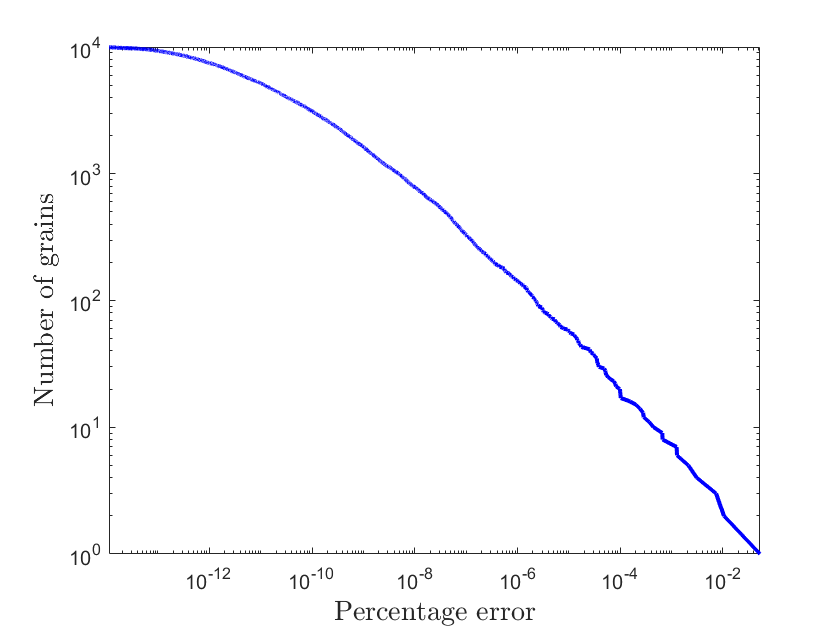


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Save the results in a txt file

x=X(:,1);
y=X(:,2);
z=X(:,3);
phaseID=ones(n,1); % all grains belong to the same phase
fileID = fopen('Weight_data_Example_5_5.txt','w');
fprintf(fileID,'%06d %5.3f  %5.3f  %5.3f  %u \r\n',length(x),L1,L2,L3,int8(periodic));
for i=1:length(x)
    fprintf(fileID,'%06d %-3.7e %-3.7e %-3.7e %-3.7e %3.1f\r\n',...
        [i,w(i),x(i),y(i),z(i),phaseID(i)]);
end
fclose(fileID);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Plot the volume errors

percentage_errors=100*abs(actual_vols-target_vols)./target_vols;
plotErrors(percentage_errors);

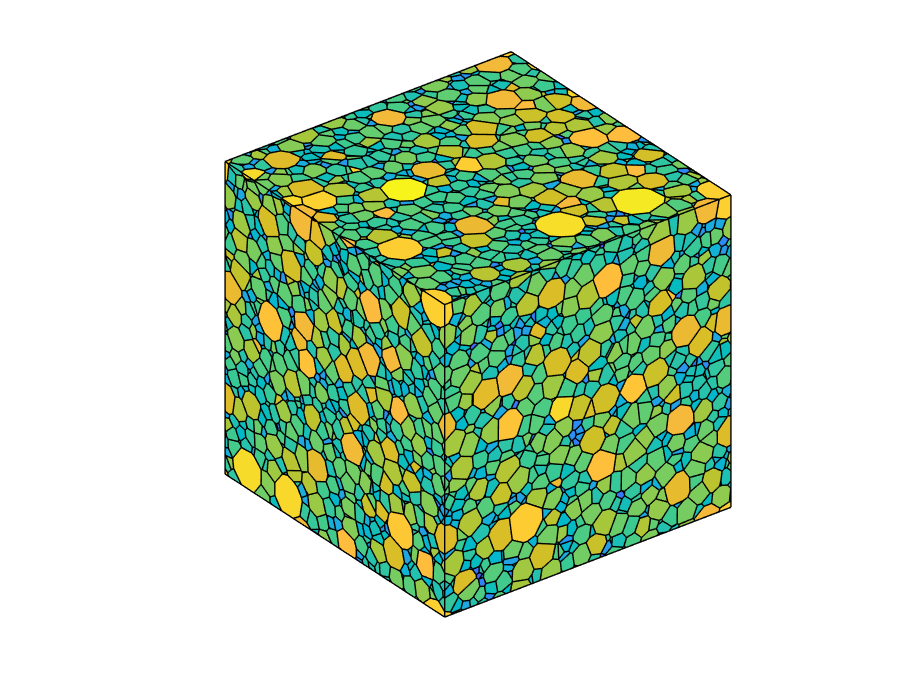

drawnow

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Plot the Laguerre tessellation

% Compute the vertices, faces, neighbours (vfn) of the Laguerre diagram
[~,~,~,vfn]=mexPDall(bx,X,w,periodic); 

% Compute which cells lie on the boundary of the box (no need to plot the 
% interior cells since they are not visible)
[polys,cellids]=intersect_cells_on_boundary_periodic(bx,vfn);

% Colour the grains according to their volume, using a log scale
colormap=parula;
myc=generateGrainColours(log(actual_vols));

% Plot the Laguerre tessellation
figure
patchpolygons(polys,cellids,myc);
view([-37.5,30])
axis equal
axis off